clear;clc;close all;

tmp=readcell('../data/Nagoya.xlsx');
tbl=table(tmp)

tbl = 34×1 table
            tmp         
    ____________________

    {'千種'}    {'東'  } 
    {'千種'}    {'中'  } 
    {'千種'}    {'昭和'} 
    {'千種'}    {'守山'} 
    {'千種'}    {'名東'} 
    {'千種'}    {'天白'} 
    {'東'  }    {'北'  }
    {'東'  }    {'中'  }
    {'東'  }    {'守山'} 
    {'北'  }    {'西'  }
    {'北'  }    {'中'  }
    {'北'  }    {'守山'} 
    {'西'  }    {'中村'} 
    {'西'  }    {'中'  }
    {'中村'}    {'中'  } 
    {'中村'}    {'中川'} 


tbl.Properties.VariableNames={'EndNodes'}

tbl = 34×1 table
          EndNodes      
    ____________________

    {'千種'}    {'東'  } 
    {'千種'}    {'中'  } 
    {'千種'}    {'昭和'} 
    {'千種'}    {'守山'} 
    {'千種'}    {'名東'} 
    {'千種'}    {'天白'} 
    {'東'  }    {'北'  }
    {'東'  }    {'中'  }
    {'東'  }    {'守山'} 
    {'北'  }    {'西'  }
    {'北'  }    {'中'  }
    {'北'  }    {'守山'} 
    {'西'  }    {'中村'} 
    {'西'  }    {'中'  }
    {'中村'}    {'中'  } 
    {'中村'}    {'中川'} 



g=graph(tbl)

g =   graph のプロパティ:

    Edges: [34×1 table]
    Nodes: [16×1 table]


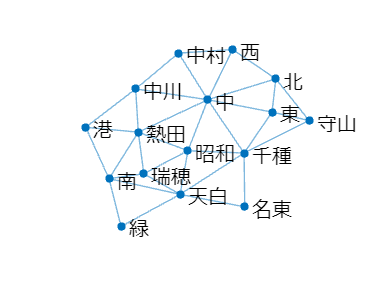


plt=plot(g);
plt.NodeFontSize=12;
plt.NodeFontName='メイリオ';
set(gca,'xcolor','none');
set(gca,'ycolor','none');
exportgraphics(gcf,'fig_Exercise_ChapA_Nagoya.pdf');